imu = imuSensor('accel-gyro-mag')

imu =   imuSensor with properties:

          IMUType: 'accel-gyro-mag'
       SampleRate: 100
      Temperature: 25
    MagneticField: [27.5550 -2.4169 -16.0849]
    Accelerometer: [1×1 accelparams]
        Gyroscope: [1×1 gyroparams]
     Magnetometer: [1×1 magparams]
     RandomStream: 'Global stream'


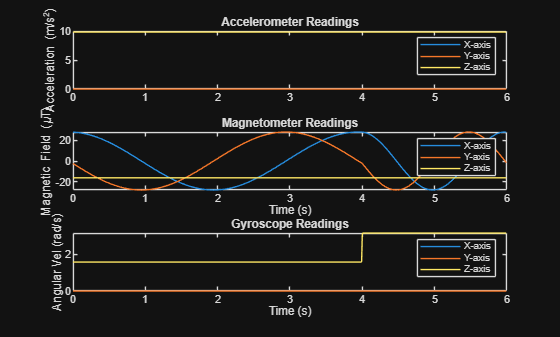


firstLoopNumSamples = imu.SampleRate*4;
secondLoopNumSamples = imu.SampleRate*2;
totalSamples = firstLoopNumSamples + secondLoopNumSamples;

traj = kinematicTrajectory('SampleRate',imu.SampleRate);

accBody = zeros(totalSamples,3);
angVelBody = zeros(totalSamples,3);
angVelBody(1:firstLoopNumSamples,3) = (2*pi)/4;
angVelBody(firstLoopNumSamples+1:end,3) = (2*pi)/2;

[~,orientationNED,~,accNED,angVelNED] = traj(accBody,angVelBody);


[accelReadings, gyroReadings, magReadings] = imu(accNED,angVelNED,orientationNED);

    

figure(1)
t = (0:(totalSamples-1))/imu.SampleRate;
subplot(3,1,1)
plot(t,accelReadings)
legend('X-axis','Y-axis','Z-axis')
ylabel('Acceleration (m/s^2)')
title('Accelerometer Readings')

subplot(3,1,2)
plot(t,magReadings)
legend('X-axis','Y-axis','Z-axis')
ylabel('Magnetic Field (\muT)')
xlabel('Time (s)')
title('Magnetometer Readings')

subplot(3,1,3)
plot(t,gyroReadings)
legend('X-axis','Y-axis','Z-axis')
ylabel('Angular Vel (rad/s)')
xlabel('Time (s)')
title('Gyroscope Readings')

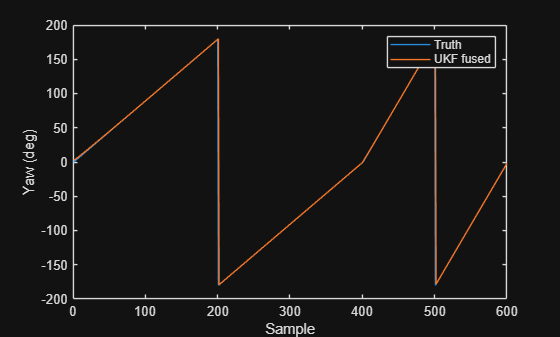

function dq = deltaQuatFromGyro(omega, dt)
% deltaQuatFromGyro  Compute incremental quaternion from gyro reading.
%
%   omega : 1x3 [wx wy wz] angular rate in rad/s (body frame)
%   dt    : scalar time step in seconds
%   dq    : 1x4 quaternion [w x y z] representing rotation over dt

    % Rotation angle over the interval
    theta = norm(omega) * dt;

    if theta < 1e-12
        % Very small rotation → approximate as identity
        dq = [1 0 0 0];
        return;
    end

    % Unit rotation axis
    u = omega / norm(omega);

    halfTheta = 0.5 * theta;
    s = sin(halfTheta);
    c = cos(halfTheta);

    % Quaternion [w x y z]
    dq = [c, u(1)*s, u(2)*s, u(3)*s];
end


function xNext = ukfStateFcn(x,u,dt)
    % x = [qw qx qy qz bgx bgy bgz]'
    % u = [wx wy wz]' gyro measurement (rad/s)
    
    q  = x(1:4).';     % row vector for quatmultiply
    bg = x(5:7).';     % 1x3

    % Bias-corrected gyro
    omega = u.' - bg;  % 1x3

    dq = deltaQuatFromGyro(omega, dt);   % 1x4 [w x y z]

    % Propagate quaternion
    qNext = quatmultiply(q, dq);         % 1x4
    qNext = qNext / norm(qNext);

    % Simple model: gyro bias is constant (random walk handled by Q)
    bgNext = bg;

    xNext = [qNext.'; bgNext.'];         % 7x1 column
end



function z = ukfMeasFcn(x, g_n, m_n)
    q = x(1:4).';              % [w x y z]

    qObj = quaternion(q);
    % Use rotateframe to go from nav -> body
    a_pred = rotateframe(qObj, g_n.');   % 1x3
    m_pred = rotateframe(qObj, m_n.');   % 1x3

    z = [a_pred.'; m_pred.'];           % 6x1
end

dt = 1/imu.SampleRate;

orientation0 = ecompass(accelReadings(1,:), magReadings(1,:));
q0 = compact(orientation0);

m_n = imu.MagneticField.';
g_n = [0; 0; 9.81];  

stateTransitionFcn = @(x,u) ukfStateFcn(x,u,dt);
measurementFcn     = @(x) ukfMeasFcn(x, g_n, m_n);

% Initial state: identity quaternion, zero bias
x0 = [q0(:);   0;0;0];

ukf = unscentedKalmanFilter( ...
    stateTransitionFcn, ...
    measurementFcn, ...
    x0, ...
    'HasAdditiveMeasurementNoise', true);

% Rough initial covariance (ask about tuning)
ukf.StateCovariance = diag([1e-4*ones(1,4), 1e-3*ones(1,3)]);

% Process and measurement noise (ask about tuning)
ukf.ProcessNoise     = diag([1e-6*ones(1,4), 1e-6*ones(1,3)]);
ukf.MeasurementNoise = diag([ (0.1*9.81)^2*ones(1,3),  (0.5)^2*ones(1,3) ]);

numSamples = size(accelReadings,1);
xHat = zeros(7,numSamples);

for k = 1:numSamples
    u_k = gyroReadings(k,:).';                       
    z_k = [accelReadings(k,:).'; magReadings(k,:).']; 

    predict(ukf, u_k);     

    correct(ukf, z_k);     

    xHat(:,k) = ukf.State;
end

q_hat = xHat(1:4,:).';  

q_rel = quatmultiply(quaternion(q_hat), conj(orientationNED));


yawPitchRoll_truth = eulerd(quaternion(orientationNED),'ZYX', 'frame');
yawPitchRoll_ukf  = eulerd(quaternion(q_hat), 'ZYX', 'frame');


yawPitchRoll_compare = eulerd(quaternion(q_rel), 'ZYX', 'frame');

figure;
plot(yawPitchRoll_truth(:,1), 'DisplayName','Truth'); hold on;
plot(yawPitchRoll_ukf(:,1),  'DisplayName','UKF fused');
xlabel('Sample'); ylabel('Yaw (deg)');
legend;

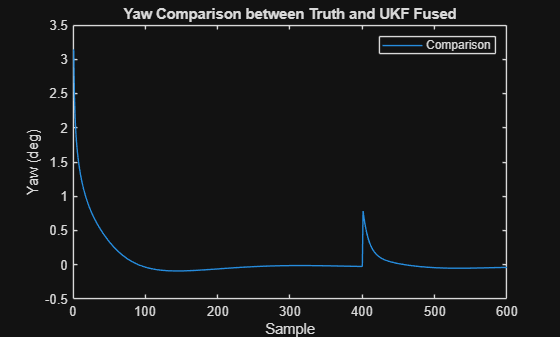


figure;
plot(yawPitchRoll_compare(:,1), 'DisplayName','Comparison');
xlabel('Sample'); ylabel('Yaw (deg)');
legend;
title('Yaw Comparison between Truth and UKF Fused');